**Ex1**

Carregue para o workspace do MATLAB as variáveis contidas no ficheiro Guitar03.mat que se encontra disponível no Moodle. Este ficheiro contém a variável 𝐱 (vetor com as amostras do sinal captado diretamente de uma guitarra elétrica, sem qualquer processamento) e a variável 𝑓𝑎, com o valor da frequência de amostragem (em Hz) considerada no processo de captura do sinal guardado em 𝐱. Usando os auriculares, ouça o som produzido por este sinal executando a função:

≫𝒔𝒐𝒖𝒏𝒅(𝐱,𝒇𝒂);

Esta função considera que a amplitude do sinal a reproduzir situa-se entre -1 e 1, pelo que, no decurso deste grupo, tenha cuidado para manter os valores dos sinais em valores baixos, na ordem de -0.1 a 0.1.

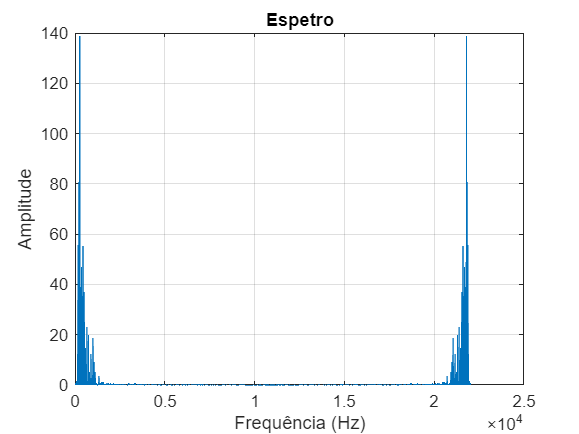

clear; clc; clean;


x_adjustado = x * 0.1;


% Reproduzir o som ajustado
sound(x_adjustado, fa);



**Ex2**

Usando a função Espetro (criada anteriormente), observe o espetro do sinal carregado na pergunta anterior, e analise as notas musicais consideradas neste sinal.

% Carregar dados do arquivo
data = load("Guitar03.mat", "fa", "x");
fa = data.fa;
x = data.x;  % Obter o sinal da guitarra
Ta = 1 / fa;  % Calcular o período de amostragem

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.


% Gerar o eixo do tempo (opcional, se necessário para análise)
t = (0:length(x)-1) * Ta;


% Calcular e plotar o espectro usando a função Espectro
[X, f] = Espectro(x, Ta);
xlim([-25, 25]);



**Ex3**

Com base no que observou na alínea anterior, desenvolva um filtro a ser aplicado sobre o espetro (i.e., um filtro que opera no domínio da frequência) que remova o conteúdo espetral desse sinal que se situe abaixo da frequência 100 Hz e acima da frequência 400Hz. Reconstrua o sinal filtrado, 𝐰, e ouça o respetivo som. Repita o teste agora para reter o conteúdo do sinal na gama de frequências de 400 Hz a 600 Hz. E, depois, para a gama de 600 kHz a 1.2 kHz.

clear; clc;

H = zeros(length(f));
H(f >= 100 & f <= 400) = 1;
H(f <= -100 & f >= -400) = 1;

sound(x, fa);

[w, t] = ReconstroiSinal(Y_filtered, )

figure;
plot(w, )

clear; clc;
Ta = 0.001;
N = 10000;

[x, t] = GeraSinal(N, Ta);


